imds = imageDatastore('C:\Users\bolub\OneDrive\Masaüstü\Ders\Year 4\FYP\pad-ufes-20\images\imgs_part_1\imgs_part_1')

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\FYP\pad-ufes-20\images\imgs_part_1\imgs_part_1\PAT_100_393_595.png';
                              ' ...\FYP\pad-ufes-20\images\imgs_part_1\imgs_part_1\PAT_100_393_898.png';
                              ' ...\FYP\pad-ufes-20\images\imgs_part_1\imgs_part_1\PAT_101_1041_651.png'
                               ... and 908 more
                              }
                     Folders: {
                              ' ...\Masaüstü\Ders\Year 4\FYP\pad-ufes-20\images\imgs_part_1\imgs_part_1'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


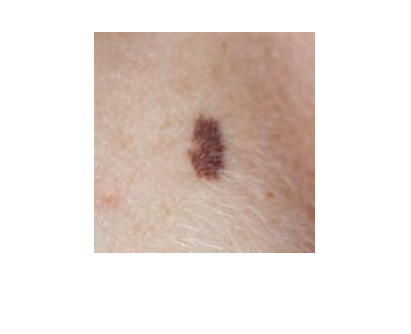


% Read the image
I = readimage(imds,2);
imshow(I);

I_gray = rgb2gray(I);

I_gray = 221×221 uint8 matrix
   157   155   156   158   160   157   156   156   157   159   160   159   158   154   155   155   156   157   158   159   159   158   158   156   154   153   153   153   153   156   157   158   158   158   157   156   156   160   161   162   164   164   165   165   164   166   166   165   165   165
   157   154   154   158   162   156   156   155   157   159   159   157   155   157   157   158   159   160   161   162   163   160   159   157   155   153   152   151   151   153   154   156   158   159   159   158   158   162   161   161   162   163   164   164   165   166   166   166   164   163
   161   157   155   157   160   158   157   157   158   159   159   156   154   158   159   160   161   162   163   164   165   163   162   159   157   155   153   152   152   153   154   157   159   160   159   158   157   162   160   160   160   160   162   164   165   166   167   166   164   162
   166   161   157   157   159   159   158   158   159   160   159 

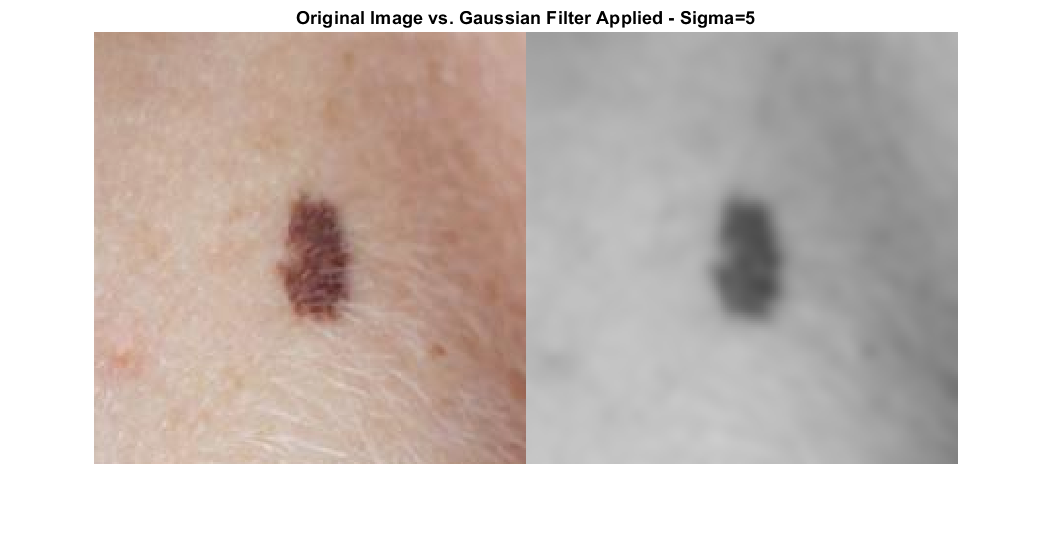


% Apply Gaussian Filter
sigma = 3;
I_filtered = imgaussfilt(I_gray,sigma);

% Montage the two together
montage({I3,I_filtered})
title('Original Image vs. Gaussian Filter Applied - Sigma=5')

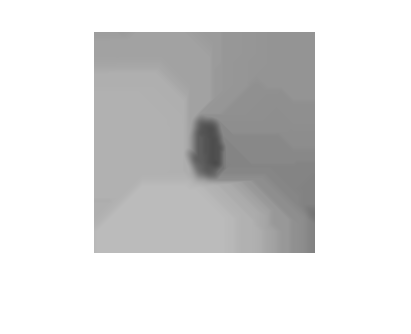


% Morphological Opening
se1 = strel('disk',50);
illumination = imopen(I_filtered,se1);
imshow(illumination)

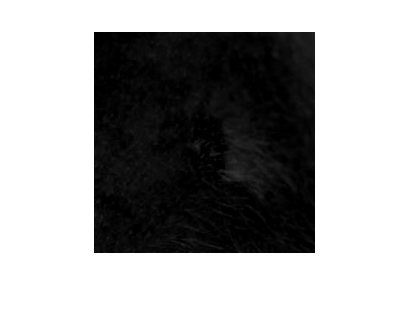


I2 = I_gray - illumination;
imshow(I2)

%{
illumination = (illumination - mean(illumination(:))) / std(illumination(:));

corrected_img = I + repmat(illumination_norm, [1 1 3]);

imshow(I)


%Morphological Closing
se = strel('disk',5);
closedMorph = imclose(I_filtered,se);

% Montage the three together
montage({I3,I_filtered,closedMorph},'size',[1 NaN])
title('Original Image vs. Gaussian Filter Applied - Sigma=5 vs. Morphological Closing Applied')

% Otsu's thresholding method
I_otsu_inter = closedMorph;
imshow(I_otsu_inter);
I_otsu_inter2 = rgb2gray(I_otsu_inter);
[counts,binLocations] = imhist(I_otsu_inter2);
Threshold = otsuthresh(counts);

%Visualize the image

I_otsu = imbinarize(I_otsu_inter2,Threshold);
imshow(I_otsu)
%}